# **Esercitazione 2 - EEG**

**Obiettivo 1: Realizzare una funzione che permetta di caricare automaticamente i dati.**

***reminder: AD è patologico (Alzheimer's disease), C è fisiologico (healthy control)***

%function my_importdata()

ciao= dir ('EEG_data');
ciao(3).name

ans = 'ad01.mat'

ciao.name

ans = '.'

ans = '..'

ans = 'ad01.mat'

ans = 'ad02.mat'

ans = 'ad03.mat'

ans = 'ad04.mat'

ans = 'ad05.mat'

ans = 'ad06.mat'

ans = 'ad07.mat'

ans = 'ad08.mat'

ans = 'ad09.mat'

ans = 'ad10.mat'

ans = 'c01.mat'

ans = 'c02.mat'

ans = 'c03.mat'

ans = 'c04.mat'

ans = 'c05.mat'

ans = 'c06.mat'

ans = 'c07.mat'

ans = 'c08.mat'

ans = 'c09.mat'

ans = 'c10.mat'

load(ciao.name)

Error using load
Unable to read file '.'. Input cannot be a directory.

my_importdata;


**Obiettivo 2: Calcolare e visualizzare lo spettro di densità di potenza per ogni dato EEG.**

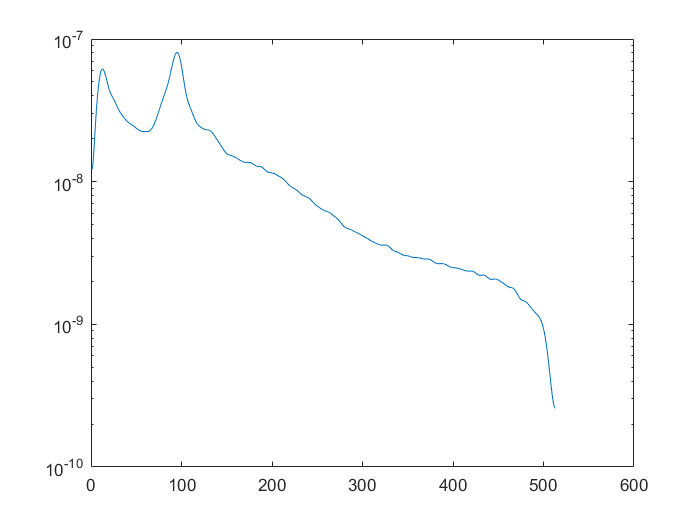

%DEFINISCO UN OVERLAP
overlap=30;

%DEFINISCO LA LUNGHEZZA DELLA FINESTRA TEMPORALE
window=100;

%FREQUENZA DI CAMPIONAMENTO
fs=100;

%nfft è il numero 1024
%The default nfft is the greater of 256 or the next power of 2 greater than the length of the segments.

[PXX10, f1] = my_pwelch(ad10, overlap, window, 1024, fs); 

potenza = PXX10;
for index = 1:9
    pippo = strcat('ad0',num2str(index));
    [PXX, f2] = my_pwelch(ad01, overlap, window, 1024, fs); 
    potenza = [potenza, PXX];
    
end

giovanni=std(potenza);

arianna=mean(potenza,2);
figure
semilogy(arianna)

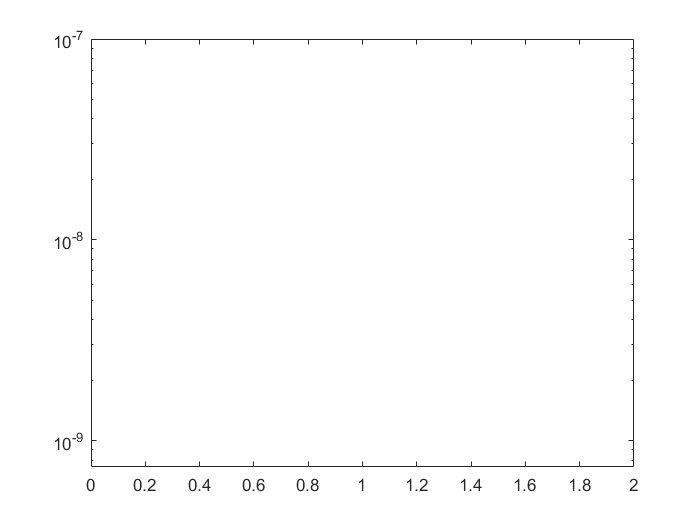

%%%%MATLAB%%%%
% [PMAT10 , f_matlab] = pwelch (ad10', window, overlap, 1024, fs );
% PMAT10=mean(PMAT10);
% 
% potenzaMAT = PMAT10;
% for index = 1:9
%     pippoMAT = strcat('ad0',num2str(index));
%     pippoMAT=pippoMAT';
%     [PMAT , f_matlab] = pwelch (pippoMAT, window, overlap, 1024, fs );
%     PMAT=mean(PMAT);
%     potenzaMAT = [potenzaMAT, PMAT];
% end

ariannaMAT=mean(potenzaMAT,2);
figure
semilogy(ariannaMAT)

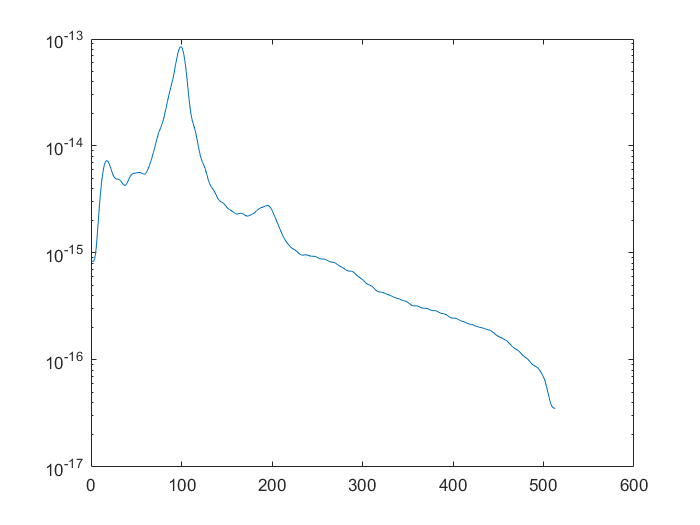


%%%%%%%%%%%%%%%%%%%%%%%%%%%

[PXC10, f1] = my_pwelch(c10, overlap, window, 1024, fs); 

potenza2 = PXC10;
for index = 1:9
    pippo1 = strcat('c0',num2str(index));
    [PXC, f2] = my_pwelch(pippo1, overlap, window, 1024, fs); 
    potenza2 = [potenza2, PXC];
end

gaia=mean(potenza2,2);
figure
semilogy(gaia)

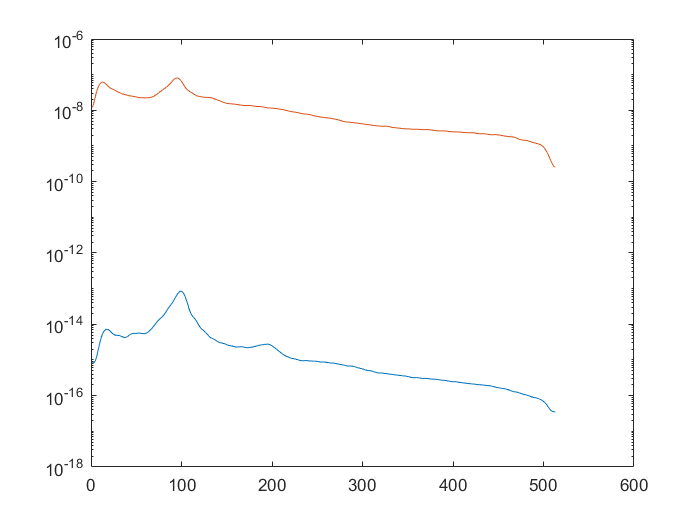

%%%%%%%
figure

semilogy(gaia)
hold on
semilogy(arianna)

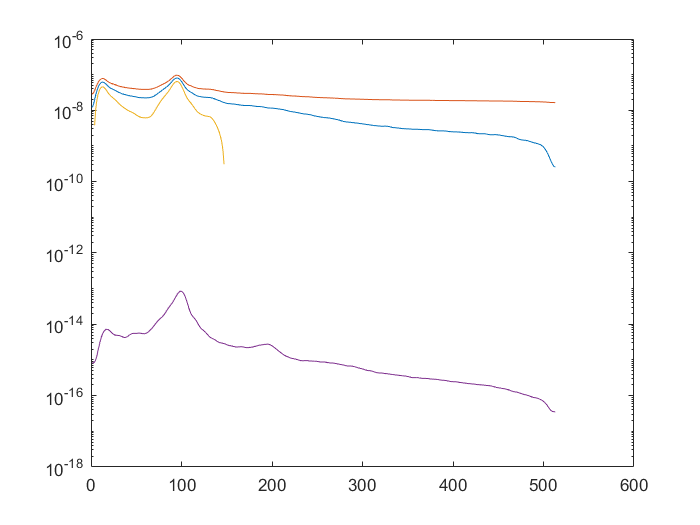


% [PXX2, f2] = my_pwelch(ad02, overlap, window, 1024, fs); 
% [PXX3, f2] = my_pwelch(ad03, overlap, window, 1024, fs);

% [pxx_matlab , f_matlab] = pwelch (ad01', window, overlap, 1024, fs );
% pmedio_matlab= mean (pxx_matlab,2);
% figure
% semilogy(pmedio_matlab)
% [pxx_matlabc , f_matlab] = pwelch (c01', window, overlap, 1024, fs );
% pmedio_matlabc= mean (pxx_matlabc,2);
% figure
% semilogy(pmedio_matlabc)



% 
% figure
% plot(pmedio)
% hold on
% plot(pmedio_matlab)



%%%%%%%%%%%%%%%%
% pmedio = zeros(,);
% for cont=1 : 10
%     if cont<10
%         cont
%        pippo = strcat('ad0',num2str(cont),'.mat');
%        [PXX, f] = my_pwelch(pippo', overlap, window, 1024, fs); 
%        pmedio(:, cont)= pmedio + mean(PXX,2);
%     figure
%     plot(pmedio)
%     end
%     if cont==10
%         load(strcat('EEG_data/ ','ad',num2str(cont),'.mat'))
%         load(strcat('EEG_data/ ','c',num2str(cont),'.mat'))
%     end
% end



%calcolo deviazione standard

desiA= std(arianna);
desiC= std(gaia);

figure
semilogy(arianna)
hold on
c=arianna+desiA;
semilogy(c)
hold on
ccc=arianna-desiA;
semilogy(ccc)
hold on
semilogy(gaia)

x=linspace(0,length(arianna),length(arianna));
%hf= fill_between (x, arianna+desiA , arianna-desiA, 1);

% Funzione per il calcolo dello spettro di densità di potenza

**Obiettivo 3: Calcolare i valori di Potenza Assoluta e Relativa per ogni gruppo.**

%function compute_abs_real_power()

**Obiettivo 4: Visualizzare i valori di Potenza Assoluta e Relativa**